# Problem 6.5

## In collaboration with Nicholas Law.

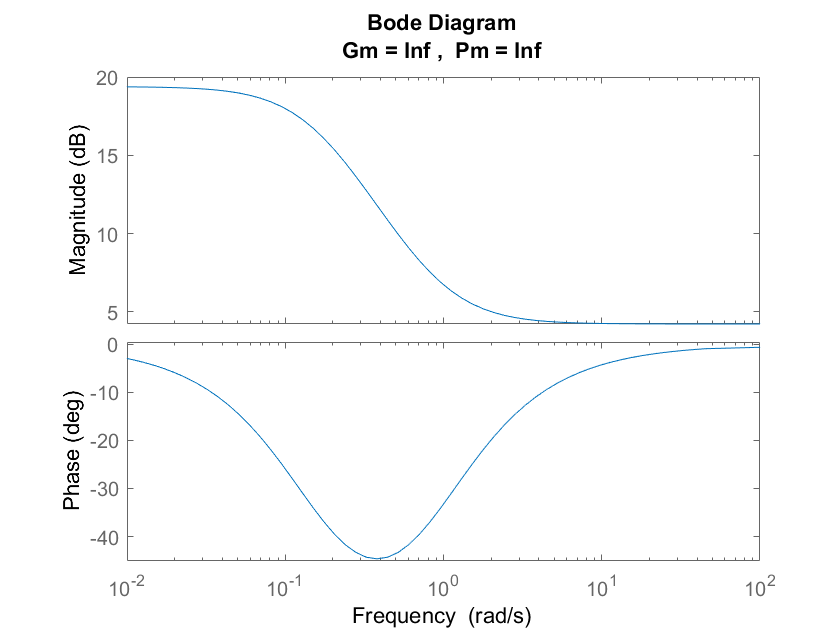

K = 9.32;
b0 = 1.1;
b1 = 1;
a1 = 1/6.3;
H = tf([10.252 9.32],[6.3 1]);
figure(1);
margin(H); %bode plot of lag network H(s)

%title('Bode Diagram: Lag Network');

## part a, Backward Difference Equivalent and h= 0.4

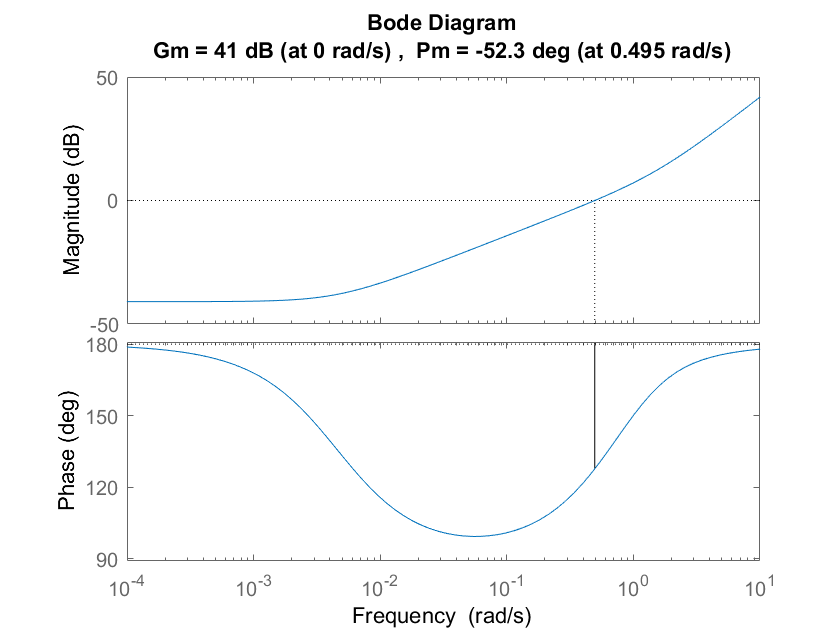


bwiggle1=b1-a1*b0;
A = [-a1];
B = [bwiggle1];
C= [1];  
D = b0;
I = eye(1);
Awiggle = inv(I-(0.4/2)*A)*(I+(0.4/2)*A);
Bwiggle = inv(I-(0.4/2)*A)*B*0.4/2;
[n,d] = ss2tf(Awiggle,Bwiggle,C,D);
beta0 = n(1)+n(2)+d*d(1);
betam = n(2)+d*d(2);
Hz_one = tf([beta0 betam],[d(1) d(2)]);
figure(10);
margin(Hz_one); %backward difference equivalent

%title('Bode Diagram: Backward Difference Equivalent; h=0.4');
%legend('Hs', 'h=0.4', 'h=1.2');

## part a, Backward Difference Equivalent and h= 1.2

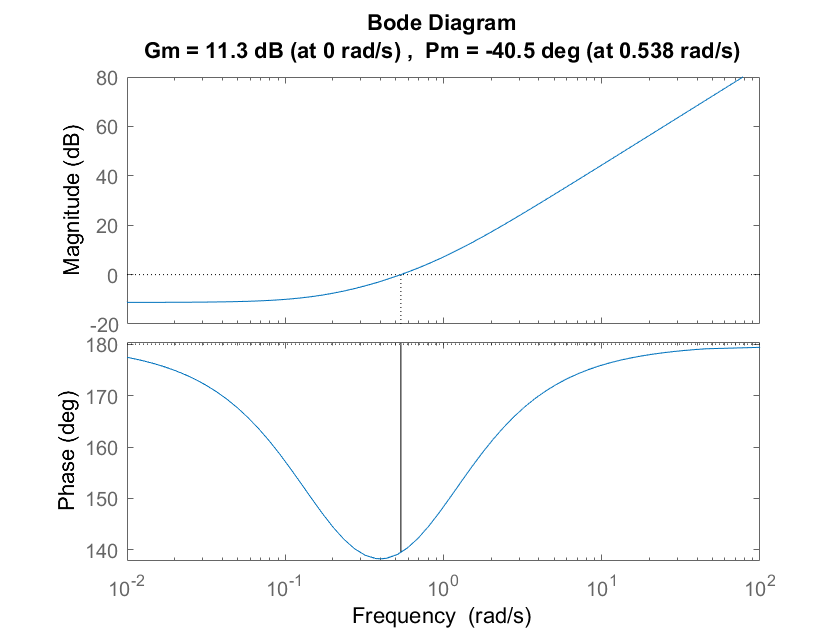


bwiggle1=b1-a1*b0;
A = [-a1];
B = [bwiggle1];
C= [1];  
D = b0;
I = eye(1);
Awiggle = inv(I-(1.2/2)*A)*(I+(1.2/2)*A);
Bwiggle = inv(I-(1.2/2)*A)*B*1.2/2;
[n,d] = ss2tf(Awiggle,Bwiggle,C,D);
beta0 = n(1)+n(2)+d*d(1);
betam = n(2)+d*d(2);
Hz_two = tf([beta0 betam],[d(1) d(2)]);
figure(11);
margin(Hz_two) %backward difference equivalent

%title('Bode Diagram: Backward Difference Equivalent');
%hold off;

## part b/e, Tustin Equivalent and Zero-Order Hold and h = 0.4

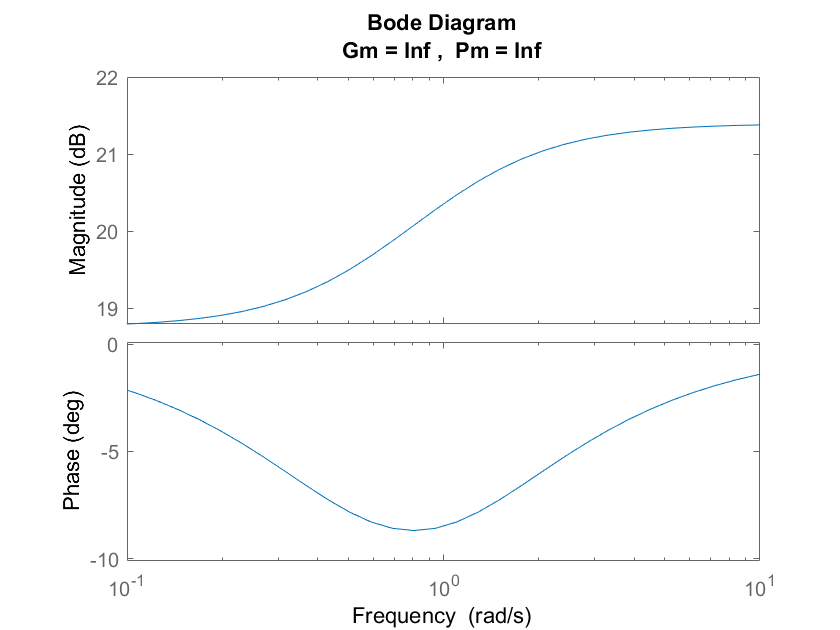


h=0.4;
beta1 = (b0-(b1*h/2))/(b0+(b1*h/2));
alpha1 = (1-a1*h/2)/(1+a1*h/2);
Kwiggle = K*((b0+b1*h/2)/(1+a1*h/2));
Hwiggle = Kwiggle*(z-beta1)/(z-alpha1);
Hz1 = tf([Kwiggle -Kwiggle*beta1],[1 -alpha1]);
Hz2 = c2d(H,h,'tustin');
figure(2);
margin(Hz1) %hand calc tustin equivalent

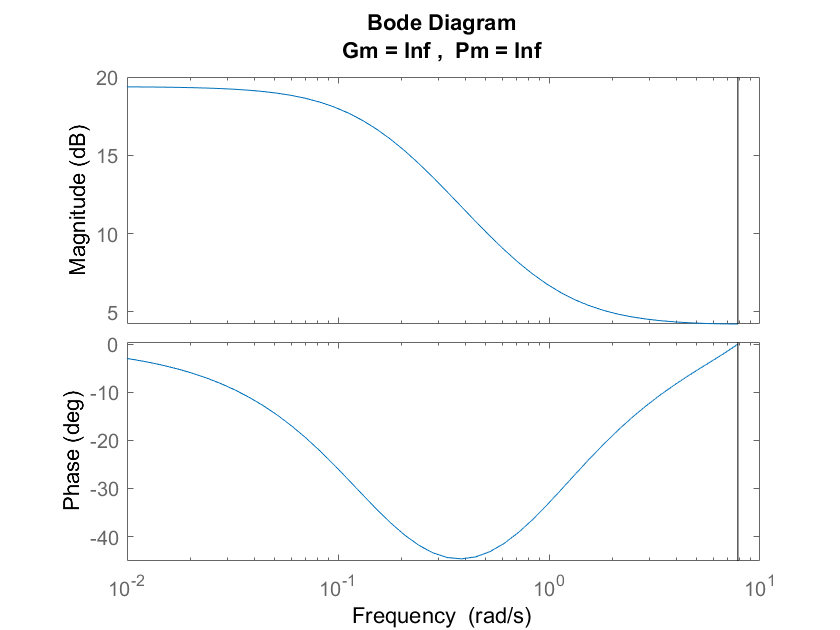

%title('Bode Diagram: Tustin Equivalent; h=0.4');
figure(3);
margin(Hz2) %tustin function, zero order hold equivalent

%title('Bode Diagram: Zero-Order Hold Equivalent; h=0.4');

## part b/e, Tustin Equivalent and Zero-Order Hold and h = 1.2

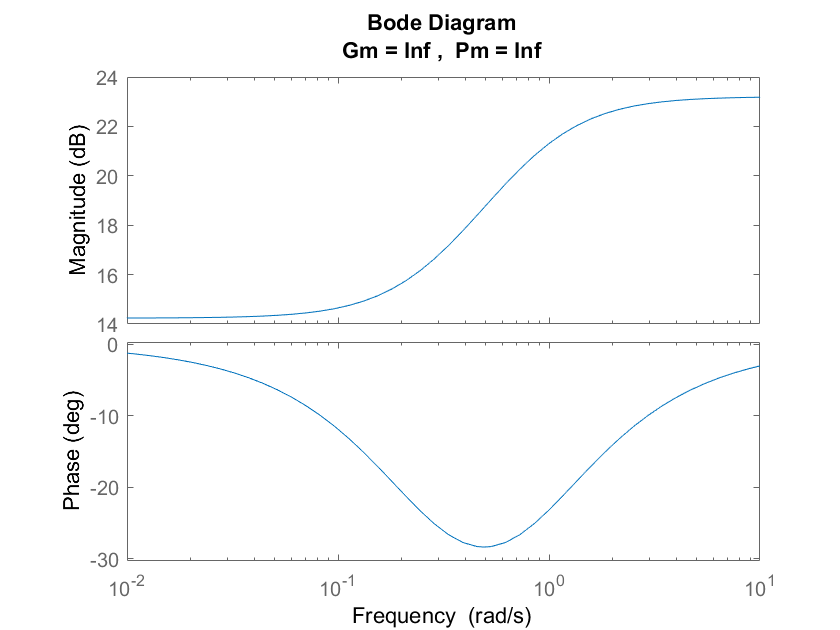


h=1.2;
beta1 = (b0-(b1*h/2))/(b0+(b1*h/2));
alpha1 = (1-a1*h/2)/(1+a1*h/2);
Kwiggle = K*((b0+b1*h/2)/(1+a1*h/2));
Hwiggle = Kwiggle*(z-beta1)/(z-alpha1);
Hz3 = tf([Kwiggle -Kwiggle*beta1],[1 -alpha1]);
Hz4 = c2d(H,h,'tustin');
figure(4);
margin(Hz3) %hand calc

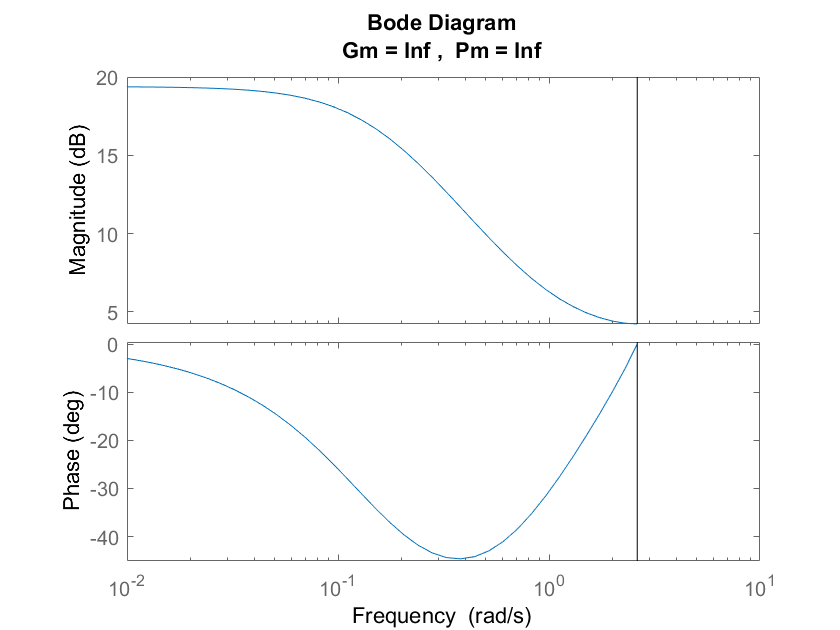

%title('Bode Diagram: Tustin Equivalent; h=1.2');
figure(5);
margin(Hz4) %tustin function, zero order hold equivalent

%title('Bode Diagram: Zero-Order Hold Equivalent; h=1.2');

## part c, Tustin Equivalent w/ Prewarp w1 = 1.9 and h = 0.4

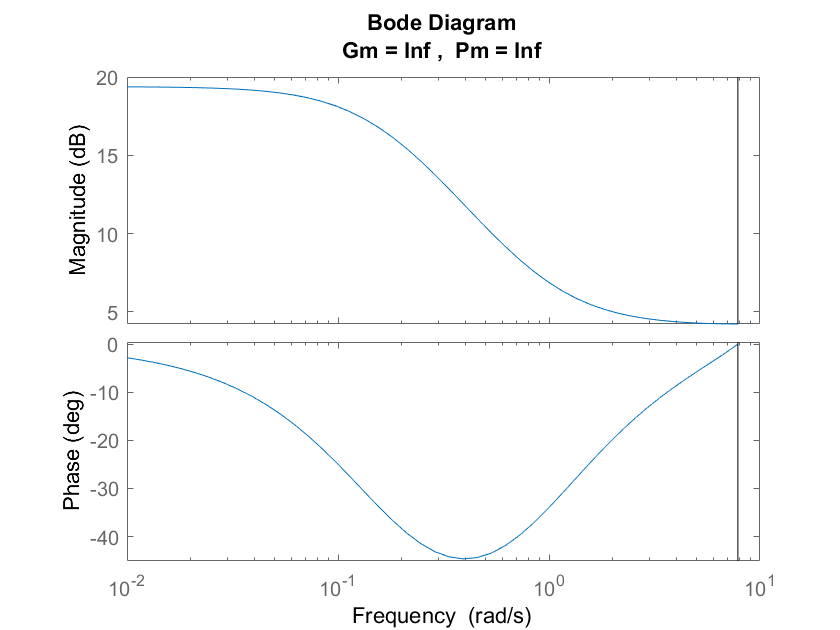


opt = c2dOptions('Method','tustin','PrewarpFrequency',1.9);
Hz5 = c2d(H,0.4,opt);
figure(6);
margin(Hz5)

%title('Bode Diagram: Tustin Equivalent w/ prewarp; h = 0.4');

## part c, Tustin Equivalent w/ Prewarp w1 = 1.9 and h = 1.2

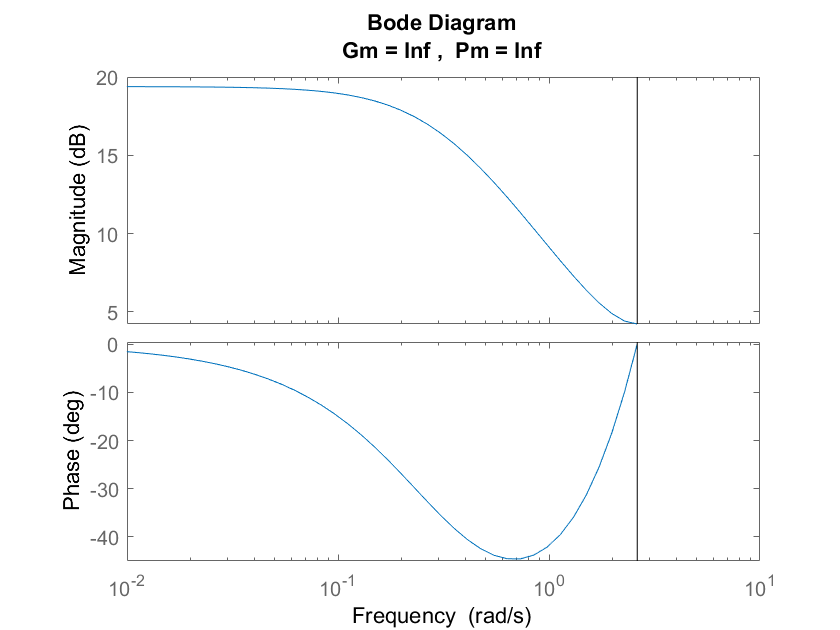


opt = c2dOptions('Method','tustin','PrewarpFrequency',1.9);
Hz6 = c2d(H,1.2,opt);
figure(7);
margin(Hz6)

%title('Bode Diagram: Tustin Equivalent w/ prewarp; h = 1.2');

## part d, Pole-Zero Mapping Equivalent and h = 0.4

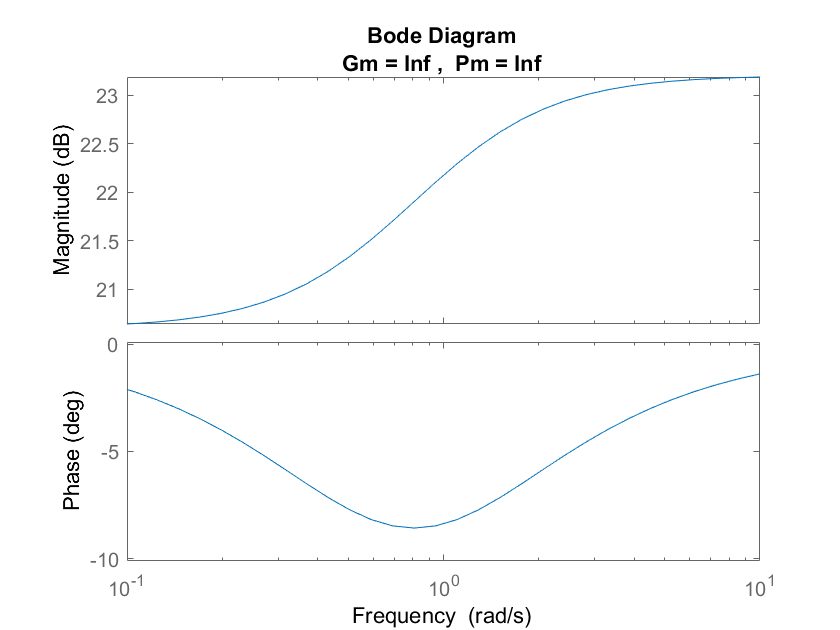


zero = exp(-1/1.1*0.4);
pole = exp(-1/6.3*0.4);
Hz7 = Kwiggle*tf([1 -zero],[1 -pole]);
figure(8);
margin(Hz7)

%title('Bode Diagram: Pole-Zero Mapping Equivalent; h = 0.4');

## part d, Pole-Zero Mapping Equivalent and h = 1.2

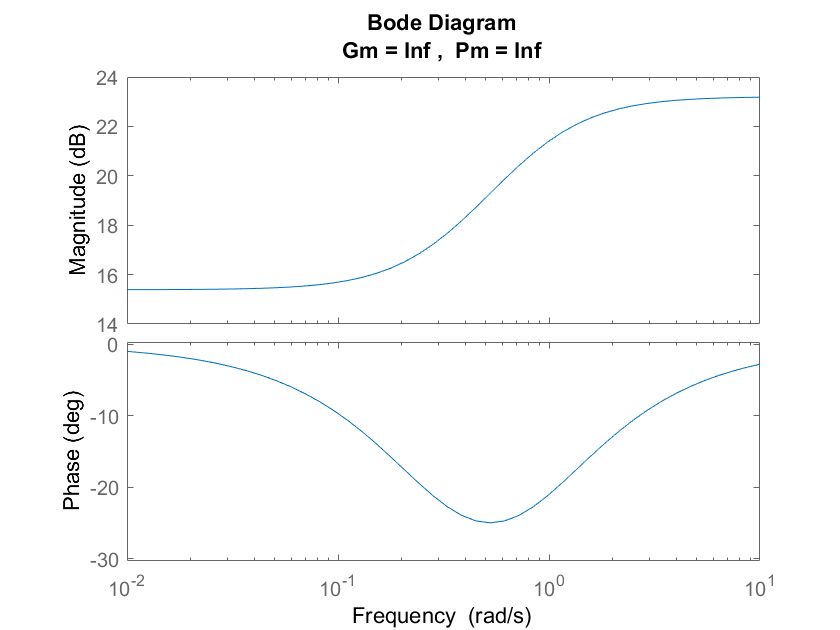


zero = exp(-1/1.1*1.2);
pole = exp(-1/6.3*1.2);
Hz8 = Kwiggle*tf([1 -zero],[1 -pole]);
figure(9);
margin(Hz8);

%title('Bode Diagram: Pole-Zero Mapping Equivalent; h = 1.2');


b. The Tustin approach is more likely to work on a lag compensator than a lead compensator. A lead compensator attempts to improve the response of a system by introducing some positive phase. It needs to be very precise, and with any discrete equivalent there is going to be a loss of phase that must be anticipated. Usually some prewarping must be done to get the system to behave correctly.

c. We don't use a Tustin transform to obtain $\tilde{G} \left(z\right)$because it comes from using a DAC on a SAMPLED version of Gs and then going through an ADC. The DAQ performs impulse sampling of Gs and then this sampled version of the signal u(kh), is what the computer sees. The hardware performs a zero-order hold to get this sampled signal. Using a Tustin approach will probably involve some more computational delay and complex hardware.